clear;clc
a = 100;
txt = split("若有零星 1304813740")

txt = 2×1 string 数组
    "若有零星"
    "1304813740"


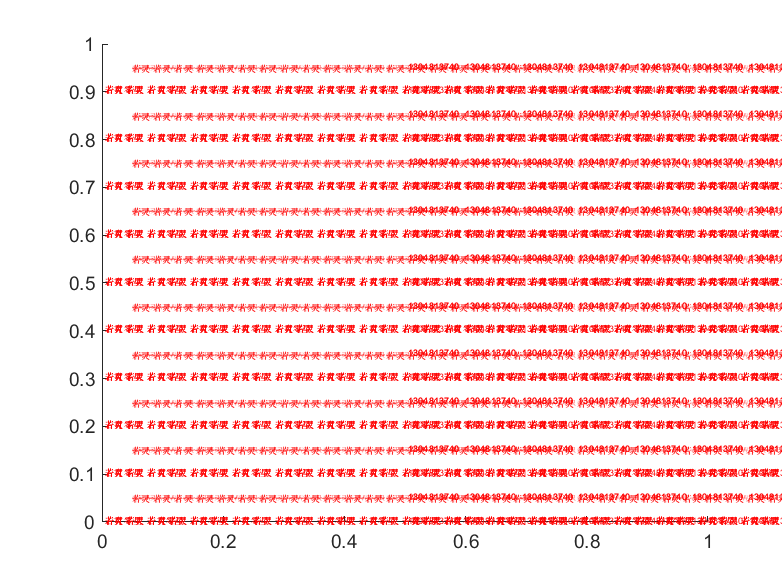

t1(1) = txt(1); t2(1) = txt(2);
for i=2:50
    t1 = string([t1(1)+'  '+txt(1)]);
    t2 = string([t2(1)+'  '+txt(2)]);
end
n = 10;
d = 0.1;
begin = [0.005,0.005];
now2 = begin + d;
x = begin(1);
y = begin(2);
figure(1);hold on
for i=1:n
    text(x,y,t1,'Color','red','FontSize',5)
    text(x+d,y+d/2,t2,'Color','red','FontSize',5)
    y = y + d;
    %     image(0.5,0.5,t1,'AlphaData',0.5)
end
hold off


J = (checkerboard(300,5,6)>0.5);
J1=J(1:2700,:);
figure
imshow(J1)
imwrite(J1,'checkerboard.png')